**PART A - LOWPASS**

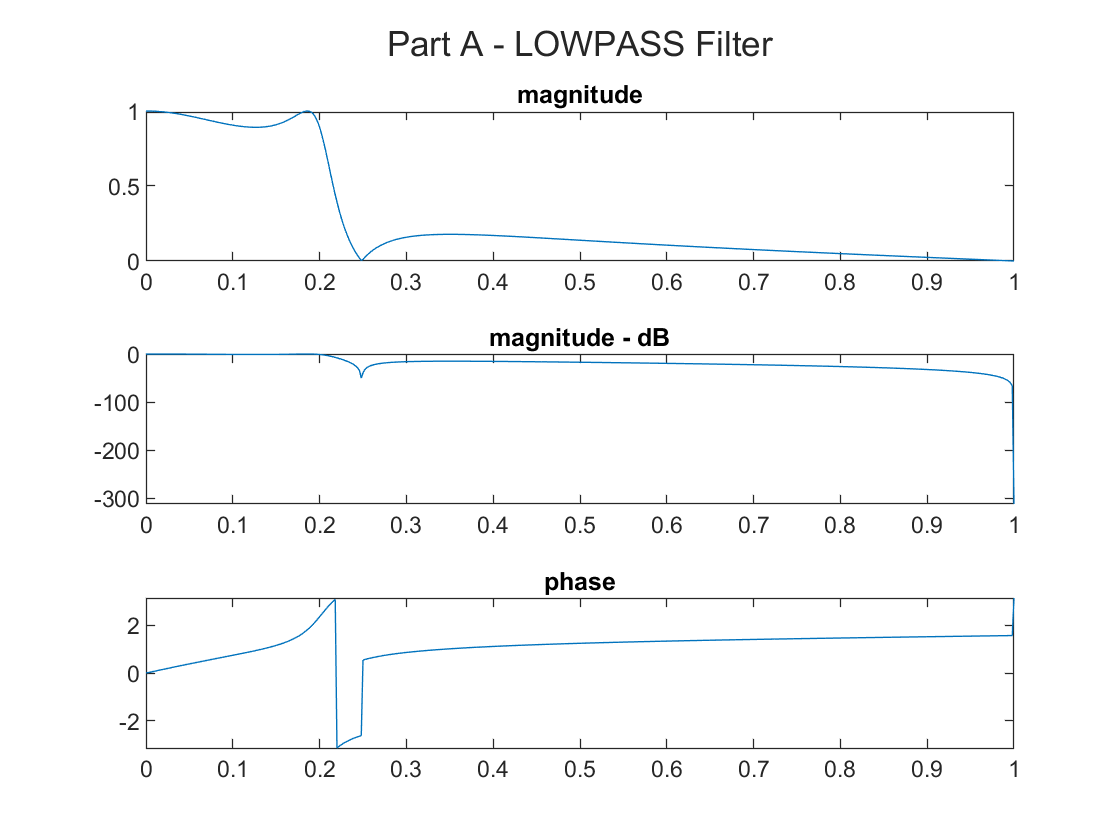

% Part A 
clear;
clc;
close all;

% Filter Specs
wp = 0.2 * pi;
ws = 0.3 * pi;
rp = 1;
as = 15;

% Analog Prototype Specs
T_a = 1;
omgP = 2 * tan(wp / 2);
omgS = 2 * tan(ws / 2);

% Analog Elliptical Filter order calculations
ep = sqrt(10^(rp/10)-1);
A = 10^(as/20);
omgC_a = omgP;
k = omgP / omgS;
k1 = ep / sqrt(A*A-1);
capk = ellipke([k.^2 1-k.^2]);
capk1 = ellipke([(k1.^2) 1-(k1.^2)]);
N = ceil(capk(1)*capk1(2) / (capk(2)*capk1(1)));

% Digital Filter Design 
wn = wp / pi;
[b, a] = ellip(N,rp,as,wn);
[db,mag,ph,~,w] = freqz_m(b,a);
% Plotting

figure(1)
t = tiledlayout(3,1);
title(t,'Part A - LOWPASS Filter')

nexttile
plot(w/pi,mag)
title('magnitude')   

nexttile
plot(w/pi,db)
title('magnitude - dB')   

nexttile
plot(w/pi,ph)
title('phase')

**Part B - HIGHPASS**

% Part A 
clear;
clc;
close all;

% Filter Specs
wp = 0.6 * pi;
ws = 0.4 * pi;
rp = 1;
as = 15;

%Analog Filter Design
[n_b, Wn_b] = ellipord(wp/pi, ws/pi, rp, as);
[b, a] = ellip(n_b,rp,as,Wn_b,"high");
[db,mag,ph,~,w] = freqz_m(b,a)

db =   -15.0000  -15.0002  -15.0009  -15.0021  -15.0038  -15.0059  -15.0085  -15.0116  -15.0151  -15.0192  -15.0237  -15.0287  -15.0341  -15.0401  -15.0465  -15.0534  -15.0609  -15.0688  -15.0771  -15.0860  -15.0954  -15.1053  -15.1157  -15.1266  -15.1380  -15.1499  -15.1624  -15.1753  -15.1888  -15.2029  -15.2174  -15.2325  -15.2481  -15.2643  -15.2810  -15.2983  -15.3162  -15.3346  -15.3536  -15.3732  -15.3934  -15.4142  -15.4355  -15.4575  -15.4801  -15.5033  -15.5272  -15.5517  -15.5769  -15.6027


mag =     0.1778    0.1778    0.1778    0.1778    0.1778    0.1777    0.1777    0.1776    0.1775    0.1774    0.1773    0.1772    0.1771    0.1770    0.1769    0.1767    0.1766    0.1764    0.1763    0.1761    0.1759    0.1757    0.1755    0.1753    0.1750    0.1748    0.1745    0.1743    0.1740    0.1737    0.1734    0.1731    0.1728    0.1725    0.1722    0.1718    0.1715    0.1711    0.1707    0.1703    0.1700    0.1695    0.1691    0.1687    0.1683    0.1678    0.1674    0.1669    0.1664    0.1659


ph =          0    0.0022    0.0044    0.0066    0.0088    0.0110    0.0133    0.0155    0.0177    0.0199    0.0221    0.0243    0.0265    0.0288    0.0310    0.0332    0.0354    0.0376    0.0399    0.0421    0.0443    0.0465    0.0488    0.0510    0.0533    0.0555    0.0577    0.0600    0.0622    0.0645    0.0667    0.0690    0.0713    0.0735    0.0758    0.0781    0.0803    0.0826    0.0849    0.0872    0.0895    0.0918    0.0941    0.0964    0.0987    0.1010    0.1033    0.1056    0.1080    0.1103


w =          0    0.0063    0.0126    0.0188    0.0251    0.0314    0.0377    0.0440    0.0503    0.0565    0.0628    0.0691    0.0754    0.0817    0.0880    0.0942    0.1005    0.1068    0.1131    0.1194    0.1257    0.1319    0.1382    0.1445    0.1508    0.1571    0.1634    0.1696    0.1759    0.1822    0.1885    0.1948    0.2011    0.2073    0.2136    0.2199    0.2262    0.2325    0.2388    0.2450    0.2513    0.2576    0.2639    0.2702    0.2765    0.2827    0.2890    0.2953    0.3016    0.3079


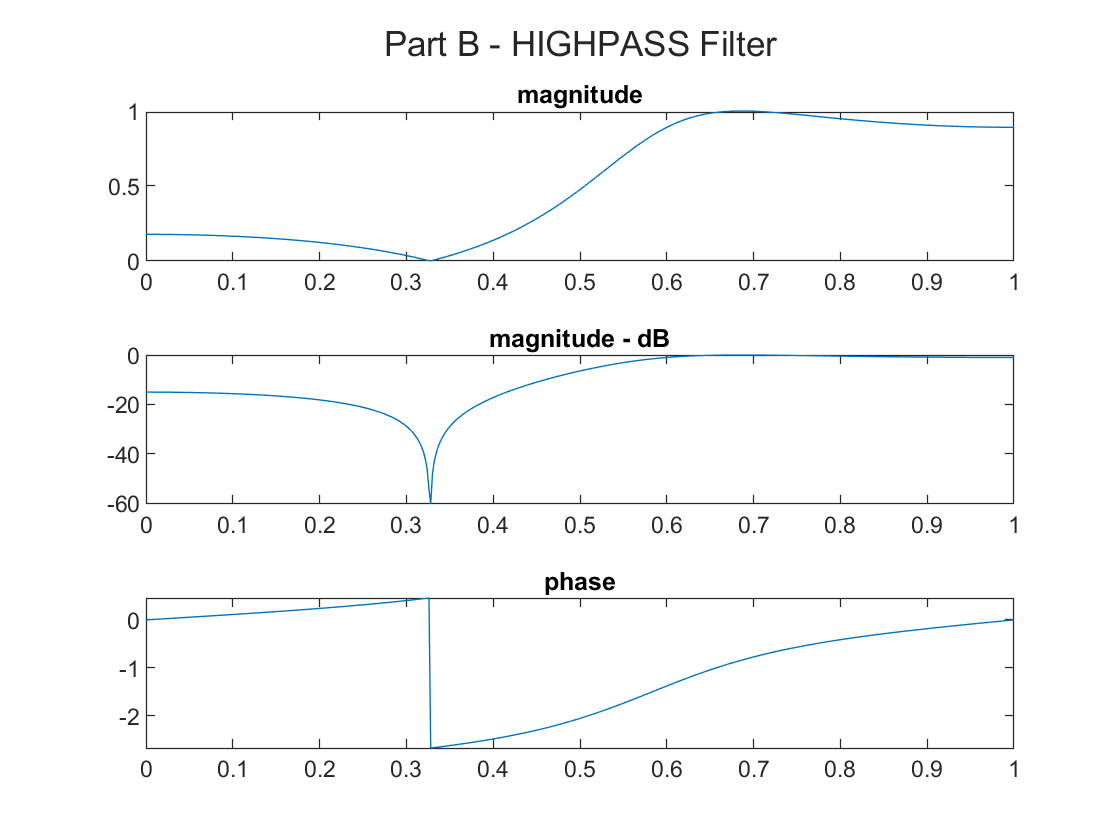

% Plotting

figure(2)
t = tiledlayout(3,1);
title(t,'Part B - HIGHPASS Filter')

nexttile
plot(w/pi,mag)
title('magnitude')   

nexttile
plot(w/pi,db)
title('magnitude - dB')   

nexttile
plot(w/pi,ph)
title('phase')

**Part C - BANDPASS**

% Part C
clear;
clc;
close all;

% Filter Spces
wp = [0.4*pi 0.6*pi];
ws = [0.3*pi 0.75*pi];
rp = 1

rp = 1

as = 40;

% Analog Filter Design 
[n, Wn] = ellipord(wp/pi, ws/pi, rp, as);
[b, a] = ellip(n,rp,as,Wn,"bandpass");
[db,mag,ph,~,w] = freqz_m(b,a)

db =   -39.9999  -40.0005  -40.0020  -40.0045  -40.0080  -40.0126  -40.0182  -40.0247  -40.0324  -40.0410  -40.0507  -40.0614  -40.0732  -40.0860  -40.0999  -40.1148  -40.1309  -40.1480  -40.1662  -40.1856  -40.2060  -40.2276  -40.2504  -40.2743  -40.2994  -40.3257  -40.3533  -40.3820  -40.4120  -40.4433  -40.4759  -40.5098  -40.5451  -40.5817  -40.6197  -40.6591  -40.7000  -40.7424  -40.7863  -40.8317  -40.8787  -40.9274  -40.9777  -41.0297  -41.0834  -41.1390  -41.1963  -41.2556  -41.3168  -41.3800


mag =     0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0098    0.0098    0.0098    0.0098    0.0097    0.0097    0.0097    0.0097    0.0096    0.0096    0.0096    0.0095    0.0095    0.0095    0.0094    0.0094    0.0094    0.0093    0.0093    0.0092    0.0092    0.0091    0.0091    0.0090    0.0090    0.0089    0.0089    0.0088    0.0088    0.0087    0.0087    0.0086    0.0085


ph =          0    0.0019    0.0038    0.0058    0.0077    0.0096    0.0115    0.0134    0.0154    0.0173    0.0192    0.0211    0.0231    0.0250    0.0269    0.0289    0.0308    0.0327    0.0347    0.0366    0.0386    0.0405    0.0425    0.0444    0.0464    0.0484    0.0504    0.0523    0.0543    0.0563    0.0583    0.0603    0.0623    0.0643    0.0663    0.0683    0.0704    0.0724    0.0744    0.0765    0.0785    0.0806    0.0827    0.0848    0.0868    0.0889    0.0910    0.0932    0.0953    0.0974


w =          0    0.0063    0.0126    0.0188    0.0251    0.0314    0.0377    0.0440    0.0503    0.0565    0.0628    0.0691    0.0754    0.0817    0.0880    0.0942    0.1005    0.1068    0.1131    0.1194    0.1257    0.1319    0.1382    0.1445    0.1508    0.1571    0.1634    0.1696    0.1759    0.1822    0.1885    0.1948    0.2011    0.2073    0.2136    0.2199    0.2262    0.2325    0.2388    0.2450    0.2513    0.2576    0.2639    0.2702    0.2765    0.2827    0.2890    0.2953    0.3016    0.3079


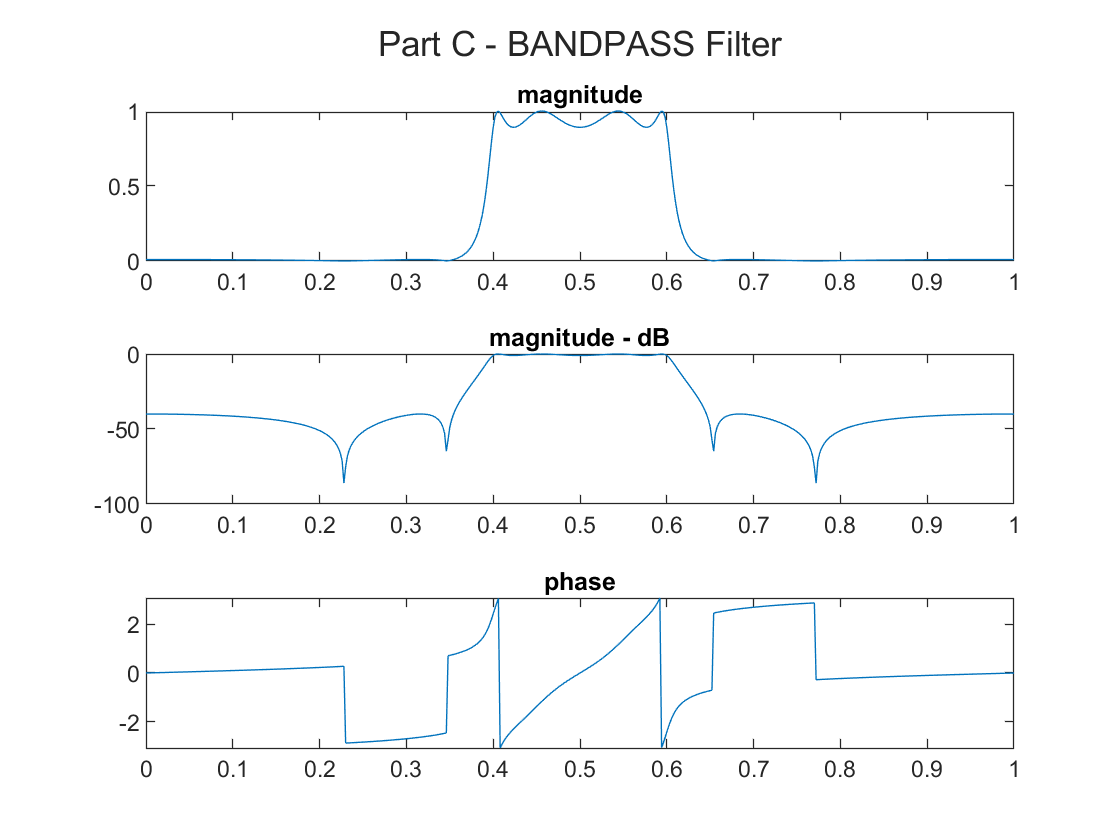

% Plotting

figure(3)
t = tiledlayout(3,1);
title(t,'Part C - BANDPASS Filter')

nexttile
plot(w/pi,mag)
title('magnitude')   

nexttile
plot(w/pi,db)
title('magnitude - dB')   

nexttile
plot(w/pi,ph)
title('phase')

**Part D - BANDSTOP**

% Part D
clear;
clc;
close all;

% Filter Spces
wp = [0.25*pi 0.8*pi];
ws = [0.4*pi 0.7*pi];
rp = 1

rp = 1

as = 40;

% Filter Design 
[n, Wn] = ellipord(wp/pi, ws/pi, rp, as);
[b, a] = ellip(n,rp,as,Wn,"stop");
[db,mag,ph,~,w] = freqz_m(b,a)

db =    -0.9999   -0.9994   -0.9980   -0.9957   -0.9924   -0.9882   -0.9831   -0.9770   -0.9701   -0.9622   -0.9535   -0.9439   -0.9333   -0.9219   -0.9097   -0.8966   -0.8827   -0.8680   -0.8524   -0.8361   -0.8191   -0.8013   -0.7828   -0.7636   -0.7437   -0.7233   -0.7022   -0.6805   -0.6584   -0.6357   -0.6126   -0.5890   -0.5651   -0.5409   -0.5163   -0.4916   -0.4667   -0.4417   -0.4166   -0.3916   -0.3666   -0.3418   -0.3171   -0.2928   -0.2689   -0.2454   -0.2224   -0.2001   -0.1784   -0.1576


mag =     0.8913    0.8913    0.8914    0.8917    0.8920    0.8924    0.8930    0.8936    0.8943    0.8951    0.8960    0.8970    0.8981    0.8993    0.9006    0.9019    0.9034    0.9049    0.9065    0.9082    0.9100    0.9119    0.9138    0.9158    0.9179    0.9201    0.9223    0.9246    0.9270    0.9294    0.9319    0.9344    0.9370    0.9396    0.9423    0.9450    0.9477    0.9504    0.9532    0.9559    0.9587    0.9614    0.9641    0.9668    0.9695    0.9721    0.9747    0.9772    0.9797    0.9820


ph =          0    0.0146    0.0292    0.0438    0.0585    0.0731    0.0878    0.1026    0.1173    0.1322    0.1471    0.1620    0.1770    0.1921    0.2073    0.2225    0.2379    0.2533    0.2689    0.2845    0.3003    0.3162    0.3323    0.3485    0.3648    0.3813    0.3980    0.4148    0.4318    0.4489    0.4663    0.4838    0.5016    0.5195    0.5377    0.5561    0.5747    0.5935    0.6126    0.6319    0.6515    0.6713    0.6914    0.7117    0.7323    0.7532    0.7743    0.7958    0.8175    0.8395


w =          0    0.0063    0.0126    0.0188    0.0251    0.0314    0.0377    0.0440    0.0503    0.0565    0.0628    0.0691    0.0754    0.0817    0.0880    0.0942    0.1005    0.1068    0.1131    0.1194    0.1257    0.1319    0.1382    0.1445    0.1508    0.1571    0.1634    0.1696    0.1759    0.1822    0.1885    0.1948    0.2011    0.2073    0.2136    0.2199    0.2262    0.2325    0.2388    0.2450    0.2513    0.2576    0.2639    0.2702    0.2765    0.2827    0.2890    0.2953    0.3016    0.3079


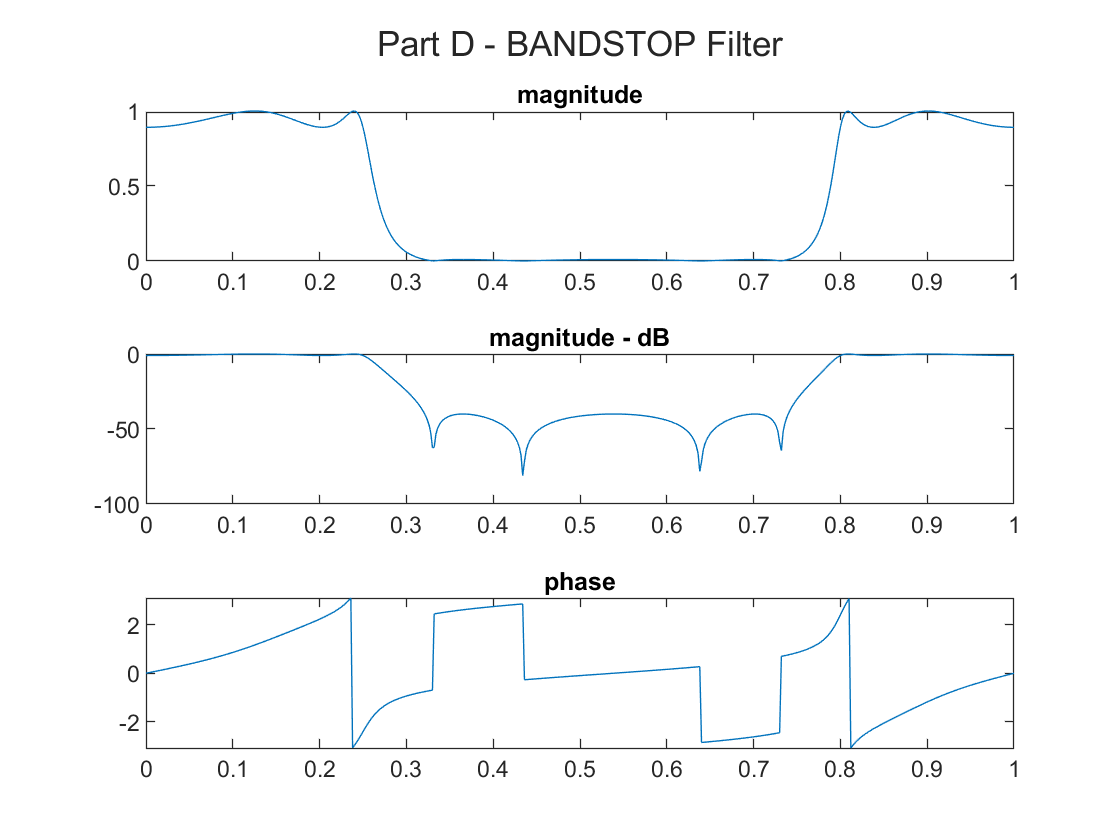

% Plotting

figure(4)
t = tiledlayout(3,1);
title(t,'Part D - BANDSTOP Filter')

nexttile
plot(w/pi,mag)
title('magnitude')   

nexttile
plot(w/pi,db)
title('magnitude - dB')   

nexttile
plot(w/pi,ph)
title('phase')